# **Digital Control System Project**

clear,clc;
close all;

# Part 0) Parameters

R = 5;
L = 5 * 10^(-6);
Kt = 10;
m = 0.6;
k = 25;
c = 0.1;
Ts = 0.02;    % Sample time
s = tf('s');
z = tf('z',Ts);

# Part A) Modeling

## 1) Dynamic equations of the system

% Ri + L(di/dt) = V

% m(dx2/t2) + c(dx/dt) + kx = Kt*i

% x1 = x
% x2 = dx/dt
% x3 = i

## 2) Transfer functions ( I(s) / V(s)  & X(s) / I(s)  & X(s) / V(s) )

% I(s)/V(s) = 1/(R + Ls) 
G1 = 1/(R + L*s);

% X(s)/I(s) = Kt/(ms^2 + cs + k)
G2 = Kt/(m*s^2 + c*s + k);

% X(s)/V(s) = Kt/((ms^2 + cs + k)(R + Ls))
Gs = G1 * G2

Gs =
 
                  10
  ----------------------------------
  3e-06 s^3 + 3 s^2 + 0.5001 s + 125
 
Continuous-time transfer function.



## 3)  Pulse transfer function of the plant

Gz = c2d(Gs,Ts)

Gz =
 
  0.0006649 z^2 + 0.0006643 z + 3.322e-12
  ---------------------------------------
   z^3 - 1.98 z^2 + 0.9967 z + 2.768e-21
 
Sample time: 0.02 seconds
Discrete-time transfer function.



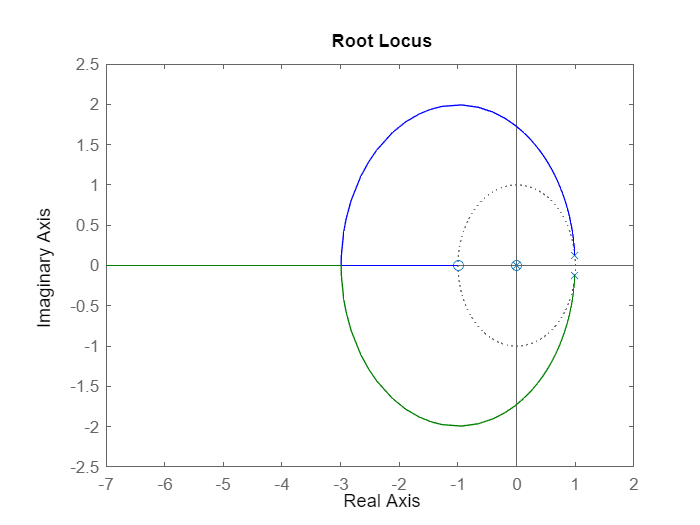

rlocus(Gz)

## 4) Continuous state-space model

% x1 = x
% x2 = dx/dt
% x3 = i
[A B Cs Ds] = tf2ss(Gs.Numerator{:},Gs.Denominator{:});

## 5) Discrete state-space model

[G H Cz Dz] = tf2ss(Gz.Numerator{:},Gz.Denominator{:})

G =     1.9801   -0.9967   -0.0000
    1.0000         0         0
         0    1.0000         0


H =      1
     0
     0


Cz = 	1.0e+-3 *

    0.6649    0.6643    0.0000


Dz = 0

# Part B) Deadbeat Response Controller

## 1) Design a deadbeat response controller to achieve zero steady-state error

Fz = 1/z;
Gd_db = minreal(Fz/(Gz * (1 - Fz)))

Gd_db =
 
   1504 z^2 - 2978 z + 1499
  --------------------------
  z^2 - 0.0009116 z - 0.9991
 
Sample time: 0.02 seconds
Discrete-time transfer function.



## 2) Response to a 10-mm step command as well as the coil current

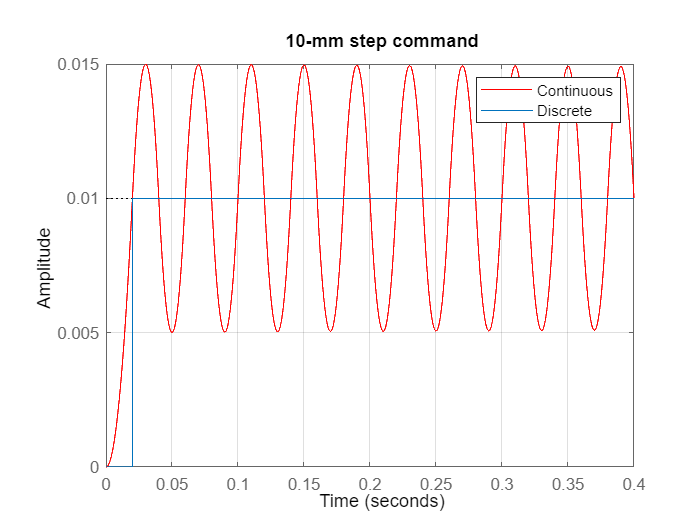

db_controller_simulink = sim("Deadbeat_controller.slx");
Y_db = db_controller_simulink.Y_db;
U_db = db_controller_simulink.U_db;
current = db_controller_simulink.current;
Rz = 10* z/(z-1) * 10^(-3);   % 10-mm step command 
plot(Y_db,'r')      % simulink
hold on 

% step(feedback(Gz*Gd_db,1)) === Fz

impulse(Fz * Rz * Ts) 
legend({'Continuous' ; 'Discrete'})
title("10-mm step command")
grid on
hold off

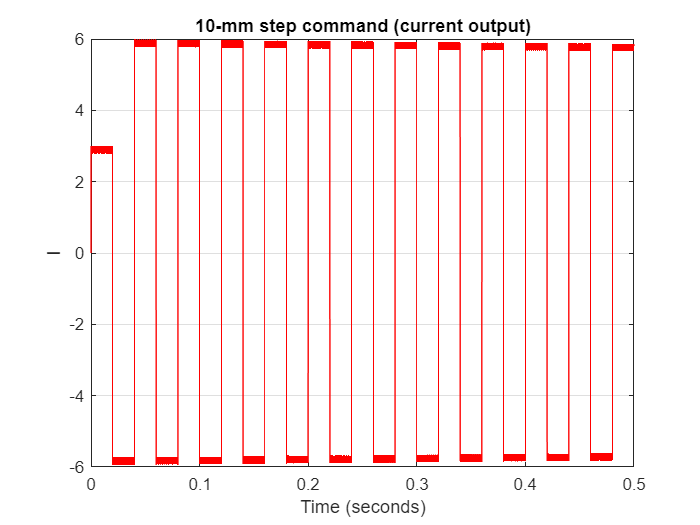

plot(current,'r')      % simulink
title("10-mm step command (current output)")
grid on
hold off

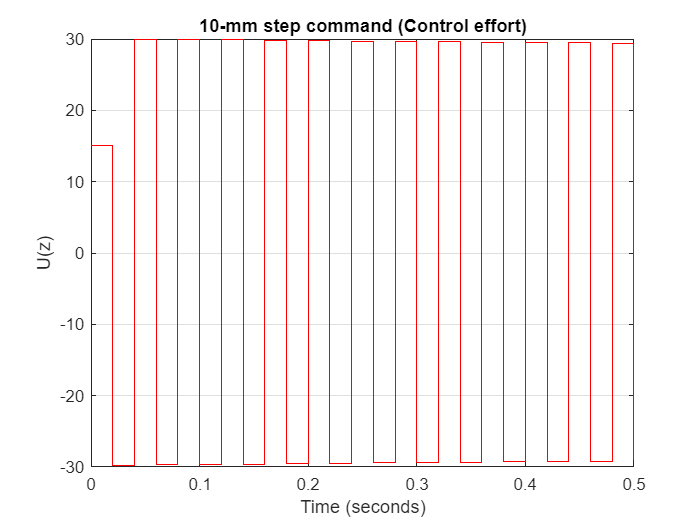

plot(U_db,'r')      % simulink
title("10-mm step command (Control effort)")
grid on
hold off

## 3) Modify the controller to remove the inter-sampling ripples

syms a0 a1
z_Gz = zero(Gz);
eq1 = (a0*(z_Gz(1)) + a1)/(z_Gz(1)^2) == 0; % (a0*z+a1)/z^2   F(z1)==0
eq2 = (a0*(1) + a1)/(1^2) == 1; % F(1) == 1

[a0 a1] = solve([eq1 eq2],[a0 a1]);
a0 = double(a0)

a0 = 0.5002

a1 = double(a1)

a1 = 0.4998

Fz_mod = (a0*z+a1)/z^2;
Gd_db_mod = minreal(Fz_mod/(Gz * (1 - Fz_mod)))

Gd_db_mod =
 
  752.3 z^2 - 1490 z + 749.8
  --------------------------
   z^2 - 0.5002 z - 0.4998
 
Sample time: 0.02 seconds
Discrete-time transfer function.



## 4) response to a 10-mm step command for the new controller and show that there  are no inter-sampling ripples.

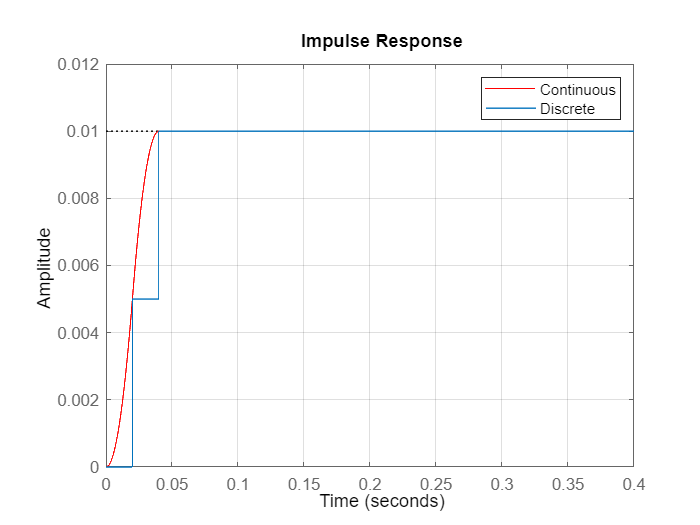

db_controller_modified_simulink = sim("Modified_Deadbeat_controller.slx");
Y_db_mod = db_controller_modified_simulink.Y_db_mod;
U_db_mod = db_controller_modified_simulink.U_db_mod;
current_mod = db_controller_modified_simulink.current_mod;

plot(Y_db_mod,'r')      % simulink
hold on 

impulse(Fz_mod * Rz * Ts) 
legend({'Continuous' ; 'Discrete'})
grid on
hold off

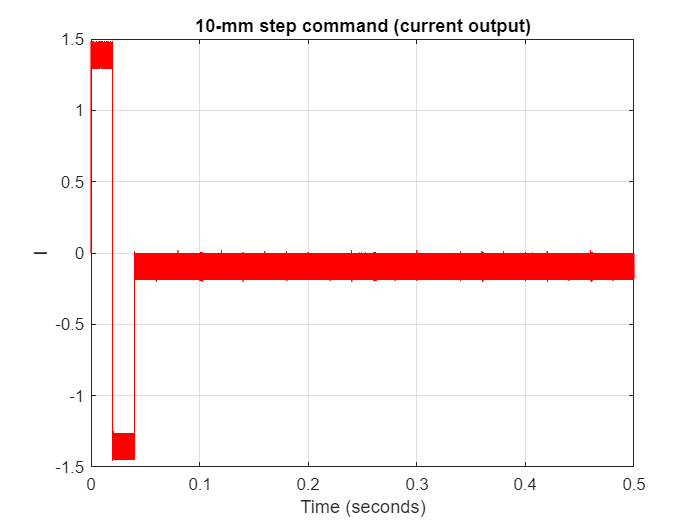

plot(current_mod,'r')      % simulink
title("10-mm step command (current output)")
grid on
hold off

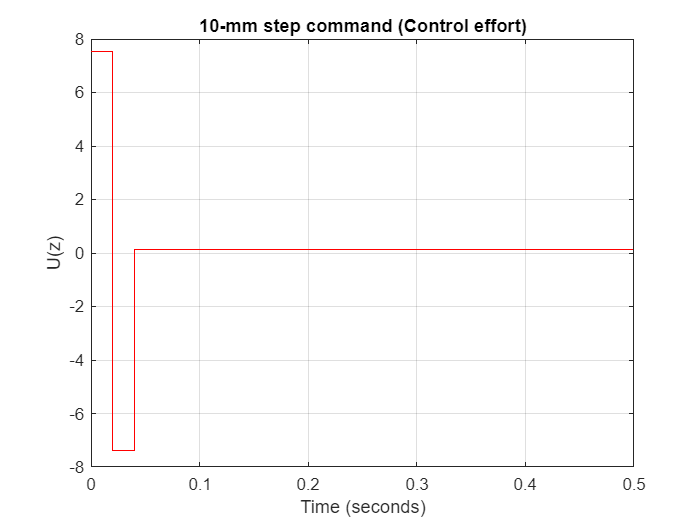


plot(U_db_mod,'r')      % simulink
title("10-mm step command (Control effort)")
grid on

# Part C) Direct Design

## 1)  Root locus design

tr = 0.1;
Mp = 10;   
wn = 1.8/tr

wn = 18

zt = 0.6;     % Graph  Mp: 10%

s1 = -wn*zt + 1i*wn*sqrt(1-zt^2)-1

s1 = -11.8000 + 14.4000i

s2 = -wn*zt - 1i*wn*sqrt(1-zt^2)

s2 = -10.8000 - 14.4000i

z1 = exp(s1*Ts)

z1 = 0.7573 + 0.2243i

z2 = exp(s2*Ts)

z2 = 0.7726 - 0.2289i

%sisotool(Gz)

%PI 
PI = (z-0.973)/(z-1);
%PD 
PD = (z-0.82)/z;
%Gain
K = 308.52;
%PID controller
Gd_RL = K*PI*PD

Gd_RL =
 
  308.5 z^2 - 553.2 z + 246.2
  ---------------------------
            z^2 - z
 
Sample time: 0.02 seconds
Discrete-time transfer function.



## 2) response to a 10-mm step command as well as the coil current. (Root Locus)

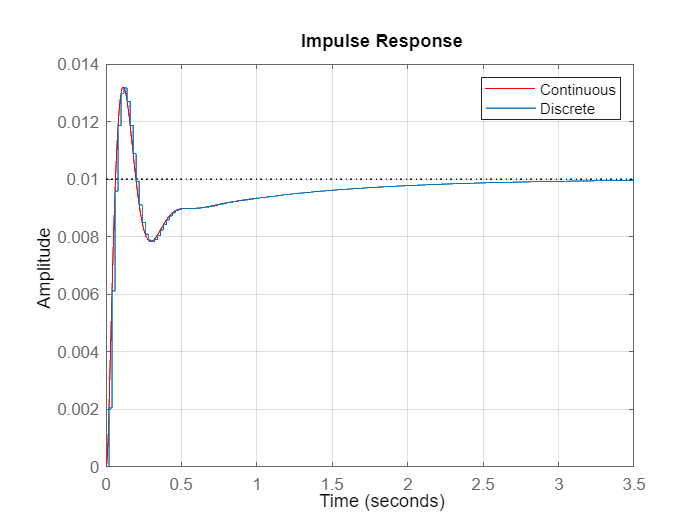

RL_controller_simulink = sim("RootLocus_controller.slx");
Y_RL = RL_controller_simulink.Y_RL;
U_RL = RL_controller_simulink.U_RL;

plot(Y_RL,'r')      % simulink
hold on 

T_RL = feedback(Gz*Gd_RL,1);
impulse(T_RL * Rz * Ts) 
grid on
legend({'Continuous' ; 'Discrete'})
hold off

# Part D) State-space Design

## 1-1) Controllability and observability of the discrete state-space model.

**a) Controllability:**

controllability = [H G*H (G^2)*H]

controllability =     1.0000    1.9801    2.9240
         0    1.0000    1.9801
         0         0    1.0000


rank(controllability)

ans = 3

Rank == 3  ---> Controllable

**b) observability:**

observability = [Cz' (G')*(Cz') ((G')^2)*(Cz')]

observability =     0.0007    0.0020    0.0033
    0.0007   -0.0007   -0.0020
    0.0000   -0.0000   -0.0000


rank(observability)

ans = 3

Rank == 3  ---> Observable

## 1-2) Controllability and observability of the system (coil current as plant output)

Gz_1 = c2d(G1,Ts);
[G_1 H_1 Cz_1 Dz_1] = tf2ss(Gz_1.Numerator{:},Gz_1.Denominator{:});
observability_1 = [Cz_1' (G_1')*(Cz_1')]

observability_1 =     0.2000         0


rank(observability_1)

ans = 1

controllability_1 = [H_1 (G_1)*(H_1)]

controllability_1 =      1     0


rank(controllability_1 )

ans = 1

Rank != 2  ---> UnObservable and Controllable

## 2) Servo system Design

GG = [G,zeros(3,1);-Cz*G,1];
HH = [H;-Cz*H];
z3 = 0;                     % zero steady-state error
z4 = 0.5;                   % unique design
Z_poles = [z1, z2, z3, z4];
K = acker(GG, HH, Z_poles);

Kp = K(1:3)

Kp =     0.9236   -0.6785   -0.0000


KI = K(4)

KI = -40.0790

## 3) Response of states to a 10-mm step command.

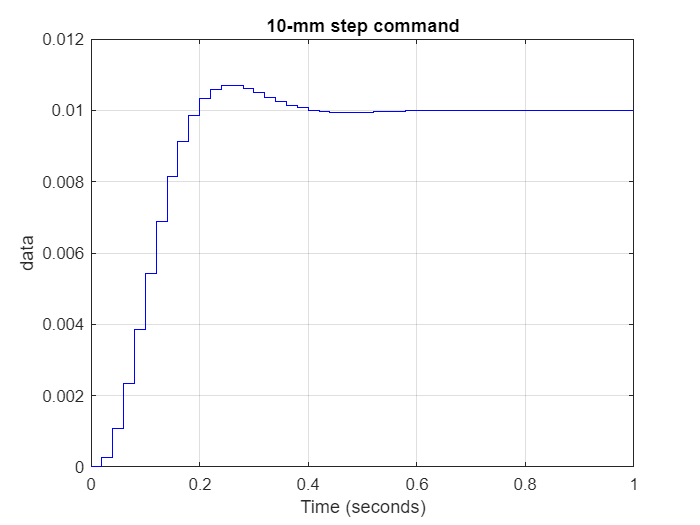

Servo_controller_simulink = sim("Servo_controller.slx");
Y_servo =Servo_controller_simulink.Y_servo;

plot(Y_servo,'b')      % simulink
title("10-mm step command")
hold on 
grid on
hold off

## 4) Full-order deadbeat-response observer

IQ = G^3;
L = IQ * ([Cz ; Cz*G ; Cz*(G^2)]^(-1))*[0 ; 0 ; 1]

L = 	1.0e+03 *

    1.8528
    1.1261
    0.3782


## 5) Modify the system to use the estimated states for feedback. Response  of the actual plant states to a 10-mm step command

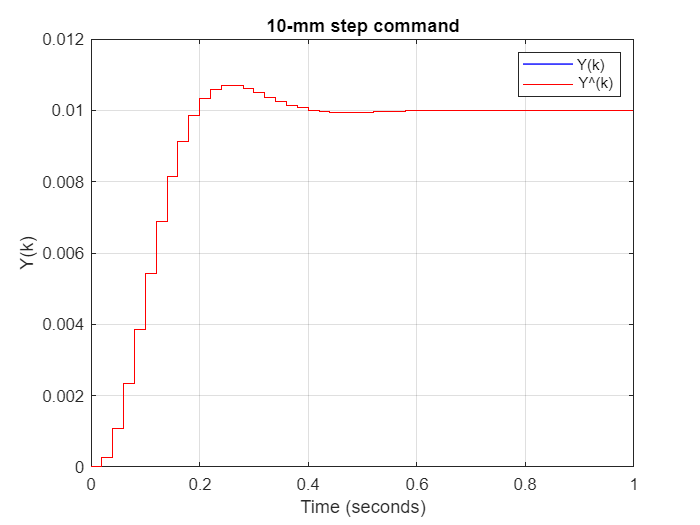

Kp_sin =     0.8919   -0.6572   -0.0000


KI_sin = -37.3947

Servo_Observer_simulink = sim("Servo_Observer.slx");
Y_servo_obs =Servo_Observer_simulink.Y_servo_obs;
Y_hat_servo_obs =Servo_Observer_simulink.Y_hat_servo_obs;

plot(Y_servo_obs,'b')          % simulink
hold on 
plot(Y_hat_servo_obs,'r')      % simulink
hold on 
grid on

title("10-mm step command")

legend({'Y(k)' ; "Y\^(k)"})
hold off